%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%                        Master Thesis - Graphs Analysis (Part 1)                          %
% Created by: B. Sc. Daniel Coronado                                                       %
% Supervised by: M. Sc. Avichal Malhotra                                                   %
% Last update: Februay 2021                                                                %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%                                    INSTRUCTIONS                                          %
% The goal of this file is to compare the graphs between the interpolation methods,        %
% (this will be a fast way to eliminate the worst scenario).                               %
% *Each line has a comment with a small description.                                       %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%======= Clean all variables================================================================
clc,clear all,close all;                          %clear all variables and close all figure.
%===========================================================================================

## ***======= Choose Analyze and Missing data =======***

Missing_data= 1; %Number of missing data to implement in the file.

Analyze = "Sheet4";     %Choose humidity or temperatura (internal/external).
                                   %File3 Has only outside temperature

## ***======= Original Data File =======***

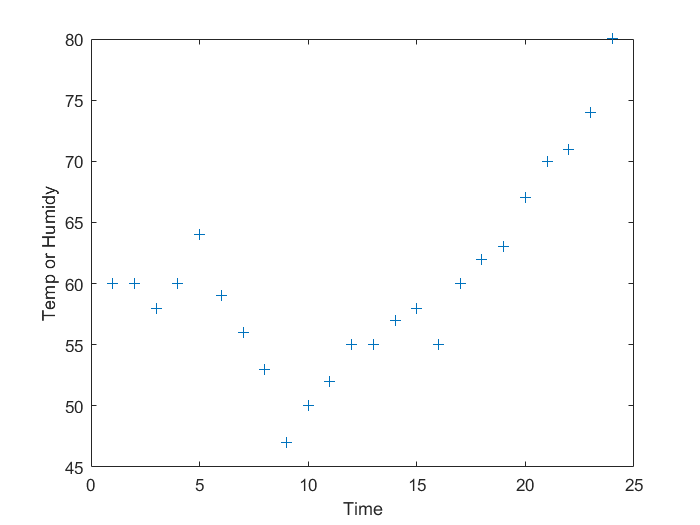

readfile = "file2.xlsx";        %Choose the Excel file to analyze
Excel= xlsread(readfile, Analyze);      %Reading Excel data 
[numDP,Time,Sensor,text] = f_ReadingFile(Excel,Analyze);
%===========================================================================================
figure(1)
plot(Time,Sensor,'+')
xlabel('Time')   
ylabel('Temp or Humidy')
saveas(figure(1),'pic_Data_Points_1.png');

## ***======= Find outliers in data =======***

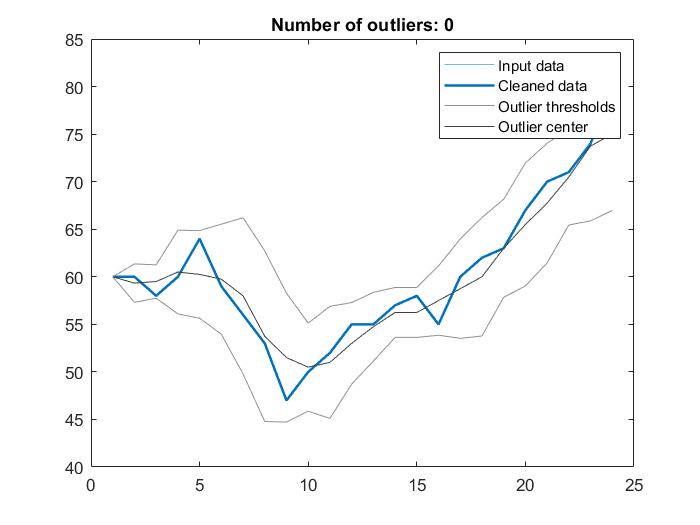

% Fill outliers
[cleanedData,outlierIndices,thresholdLow,thresholdHigh,center] = ...
    filloutliers(Sensor,'linear','movmean',4,'ThresholdFactor',1.75);

% Display results
clf
plot(Sensor,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on
plot(cleanedData,'Color',[0 114 189]/255,'LineWidth',1.5,...
    'DisplayName','Cleaned data')

% Plot outliers
plot(find(outlierIndices),Sensor(outlierIndices),'x','Color',[64 64 64]/255,...
    'DisplayName','Outliers')
title(['Number of outliers: ' num2str(nnz(outlierIndices))])

% Plot filled outliers
plot(find(outlierIndices),cleanedData(outlierIndices),'.','MarkerSize',12,...
    'Color',[217 83 25]/255,'DisplayName','Filled outliers')

% Plot outlier thresholds
plot([(1:numel(Sensor))'; missing; (1:numel(Sensor))'],...
    [thresholdHigh(:); missing; thresholdLow(:)],'Color',[145 145 145]/255,...
    'DisplayName','Outlier thresholds')

% Plot outlier center
plot(center,'Color',[64 64 64]/255,'DisplayName','Outlier center')

hold off
legend
clear outlierIndices thresholdLow thresholdHigh center

saveas(gcf,'pic_outliers.png');

## *======= Find Local and  Global (Maximum and Minimum) =======*

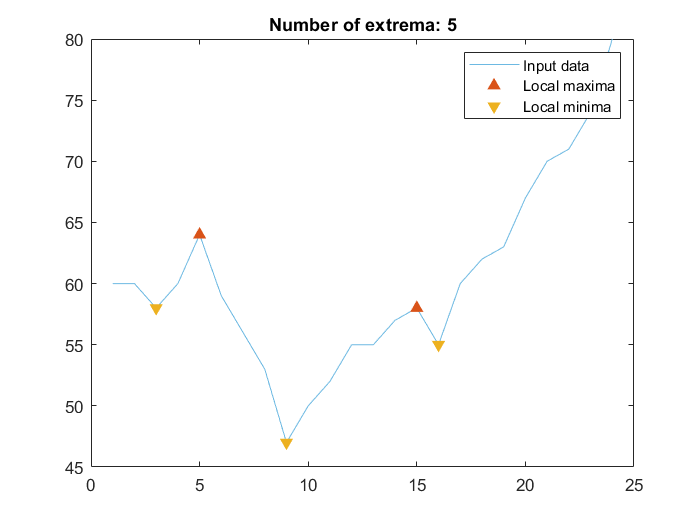

% Find local maxima and minima
maxIndices = islocalmax(Sensor,'SamplePoints',Time);
minIndices = islocalmin(Sensor,'SamplePoints',Time);

% Display results
clf
plot(Time,Sensor,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on

% Plot local maxima
plot(Time(maxIndices),Sensor(maxIndices),'^','Color',[217 83 25]/255,...
    'MarkerFaceColor',[217 83 25]/255,'DisplayName','Local maxima')

% Plot local minima
plot(Time(minIndices),Sensor(minIndices),'v','Color',[237 177 32]/255,...
    'MarkerFaceColor',[237 177 32]/255,'DisplayName','Local minima')
title(['Number of extrema: ' num2str(nnz(maxIndices)+nnz(minIndices))])
hold off
legend
saveas(gcf,'pic_max_min.png');

## ***======= Find Change Points =======***

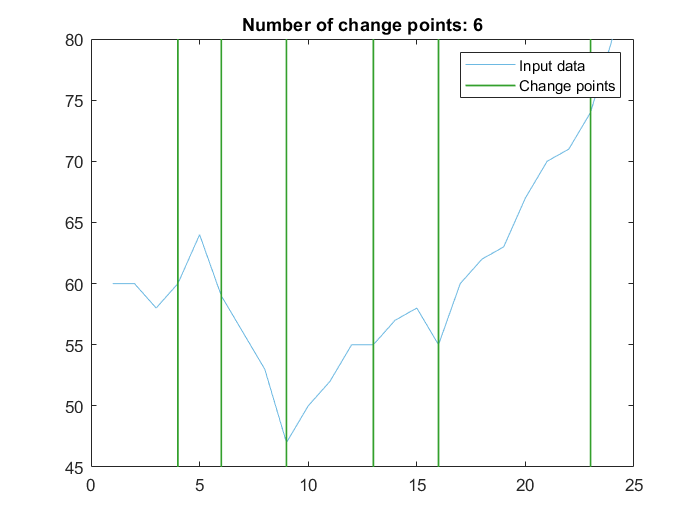

% Find change points
changeIndices = ischange(Sensor,'linear','MaxNumChanges',6,...
    'SamplePoints',Time);

% Display results
clf
plot(Time,Sensor,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on

% Plot change points
x = repelem(Time(changeIndices),3);
y = repmat([ylim(gca) NaN]',nnz(changeIndices),1);
plot(x,y,'Color',[51 160 44]/255,'LineWidth',1,'DisplayName','Change points')
title(['Number of change points: ' num2str(nnz(changeIndices))])

hold off
legend
clear x y
saveas(gcf,'pic_Change_points.png');

## *======= Interp1 (Linear interpolation) =======*

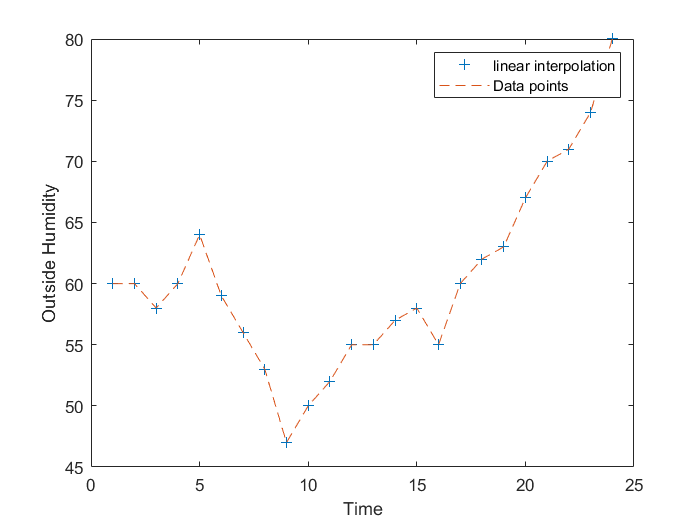

xq = 1:0.1:24;
vq = interp1(Time,Sensor,xq,'linear');  %Sprintf(formatSpec,degree)

plot(Time,Sensor,'+',xq,vq,'--')
f_plot_legend(' ','linear interpolation','Time',text,'Data points')
saveas(gcf,'pic_Interp_Linear.png');

## *======= Polyfit (Global Polynomial Curve) =======*

In this situation to make a polynomial interpolation in a "local way" you need to use Spline 

Those of us without the Curve Fitting Toolbox (like me) would of course have to use `polyfit`. (With the Statistics Toolbox and Optimization Toolbox, I can do all the other curve-fitting I need to do.) The one advantage I see to `polyfit` is that as I understand it, `fit` by default scales and centres the variables, whereas in `polyfit` that’s an option.

This is a bad idea because they do a global equation with all points and not a local equation for the range of the missing data.

You can do also a really high degree order because this can cause an effect callend Polynomial wiggle. (Google to see images)

Usualy in polynomial interpolations there is a problem called over fitting

***Choose the degree of the global polynomial curve***

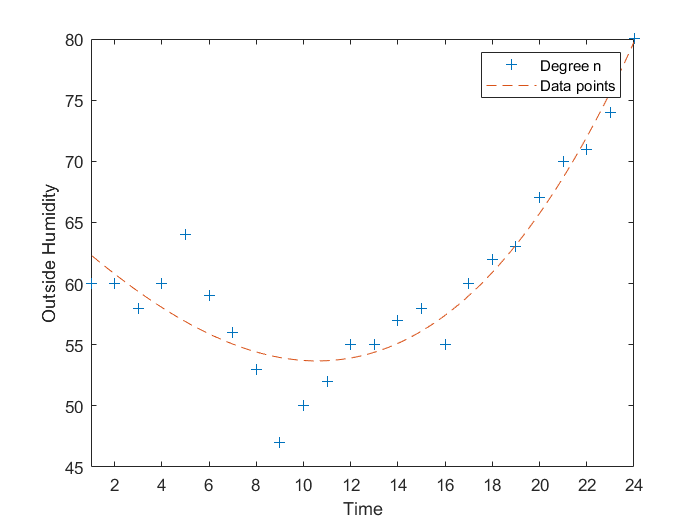

Degree = 3;
p = polyfit(Time, Sensor, Degree);
x1 = linspace(0,length(Time),1000);
y1 = polyval(p,x1);

plot(Time, Sensor,'+',x1,y1,'--')
f_plot_legend(" ",'Degree n','Time',text,'Data points')
xlim([1 24])
ylim([45 80]) %[22 25] [9 15] [40 54] [60 85]
saveas(gcf,'pic_Interp_polynomial.png');

## *======= Fit (Local Polynomial) =======*

I would like to detect where the missing data is and make a local polynomial equation, this will make the curve more smooth and reduce the erros. However, there are more better options available.

This need also need to detect how many data you have before and after the missing data. With this number you can decide the polynomial order and and make the local curve.

***Choose the degree of the global polynomial curve***

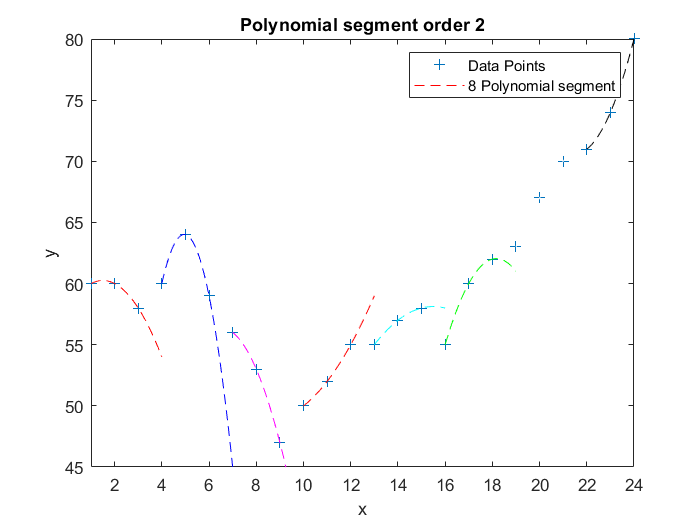

Interval =8;
Degree =2;
plot(Time,Sensor,'+')
f_plotpoli(Time, Sensor, Interval,Degree)
xlim([1 24])
ylim([45 80]) %[22 25] [9 15] [40 54] [60 85]

## *=======Interp1 (Nearest)=======*

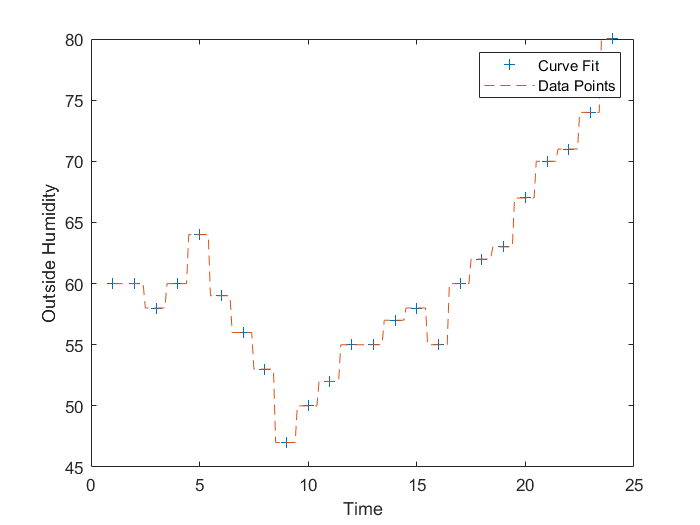

xq3 = 1:0.1:24;
vqq = interp1(Time,Sensor,xq3,'nearest');  %Sprintf(formatSpec,degree)
plot(Time,Sensor,'+',xq3,vqq,'--')
f_plot_legend(' ','Curve Fit','Time',text,'Data Points')
saveas(gcf,'pic_Interp_nearst.png');

## =======*Interp1 (*Pchip*)*=======

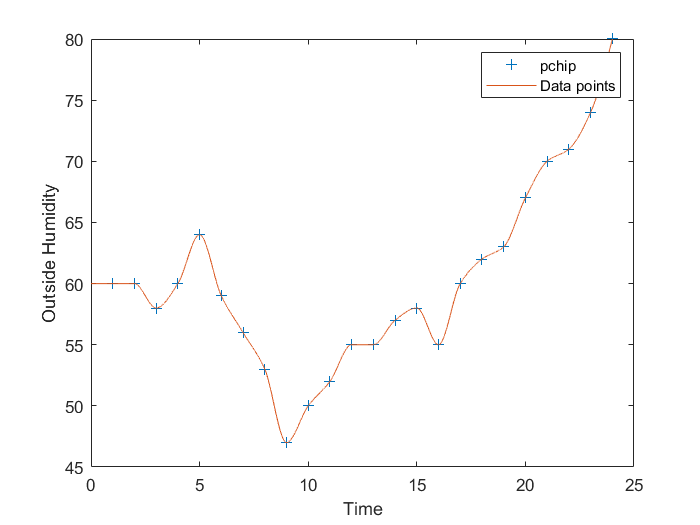


p = pchip(Time,Sensor,0:0.001:length(Time));
plot(Time, Sensor,'+',0:0.001:length(Time),p,'-')
f_plot_legend(' ','pchip','Time',text,'Data points')
saveas(gcf,'pic_Interp_Pchip.png');

## ***=======****Interp1 (****Spline****)****=======***

This is much better than polynomial curve because it "forces" the curve go through the knownpoints and create the curve. There is a better fit than polinomial. 

Usualy in polynomial interpolations there is a problem called over fitting, this (spline) makes the curve not so smooth.

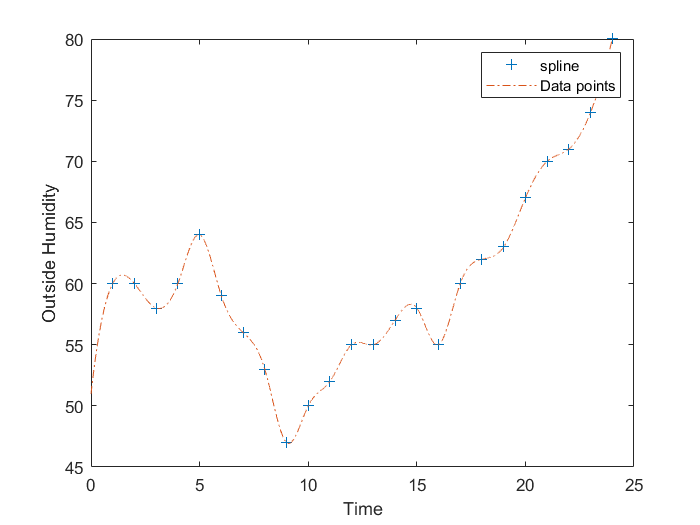

s = spline(Time,Sensor,0:0.001:length(Time));
plot(Time, Sensor,'+',0:0.001:length(Time),s,'-.')
f_plot_legend(' ','spline','Time',text,'Data points')
saveas(gcf,'pic_Interp_Spline.png');

## ***======= ****Interp1 (****Makema)=======***

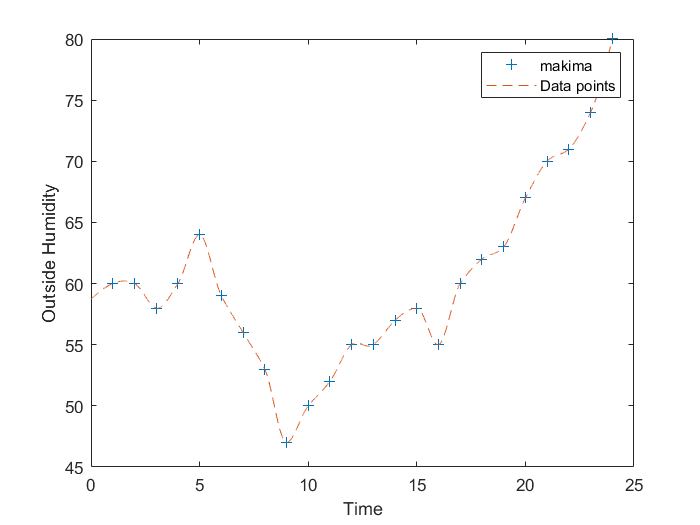

m = interp1(Time,Sensor,0:0.001:length(Time),'makima');
plot(Time, Sensor,'+',0:0.001:length(Time),m,'--')
f_plot_legend(' ','makima','Time',text,'Data points')
saveas(gcf,'pic_Interp_Makema.png');

## **======= Combination (Full Plot) =======**

***Choose the function to be plot***

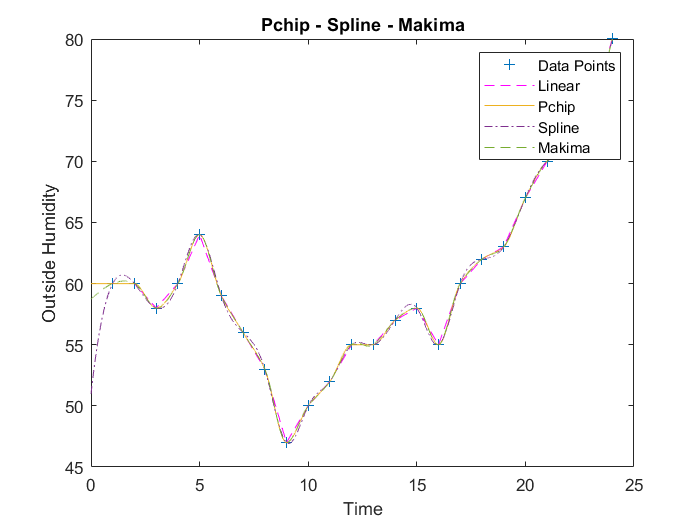

Method1 = true;  % Linear Interpolation
Method2 = false;  % Polyfit Curve and number of polinomil order
Method3 = false;  % Fit (Local Polynomial)
Method4 = false;  % Nearest
Method5 = true;  % Pchip
Method6 = true;  % Spline
Method7 = true;  % Makema


plot(Time,Sensor,'+')
f_combplot(xq,vq,x1,y1,Time,Sensor,Interval,Degree, xq3,vqq,p,s,m,Method1,Method2,Method3,Method4,Method5,Method6,Method7,text)
title('Pchip - Spline - Makima')
legend('Data Points','Linear','Pchip' , 'Spline', 'Makima')
saveas(gcf,'pic_Interp_Join.png');

## ***======= *****Combination (Local Plot)*****  =======***

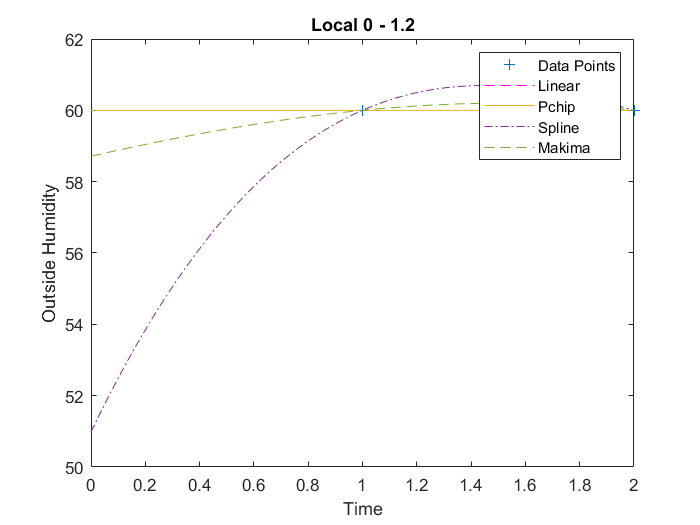

plot(Time,Sensor,'+')
f_combplot(xq,vq,x1,y1,Time,Sensor,Interval,Degree, xq3,vqq,p,s,m,Method1,Method2,Method3,Method4,Method5,Method6,Method7,text)
hold on
title('Local 0 - 1.2')
legend('Data Points','Linear','Pchip' , 'Spline', 'Makima')
xlim([0.000 2])
hold off
saveas(gcf,'pic_Interp_Local1.png');

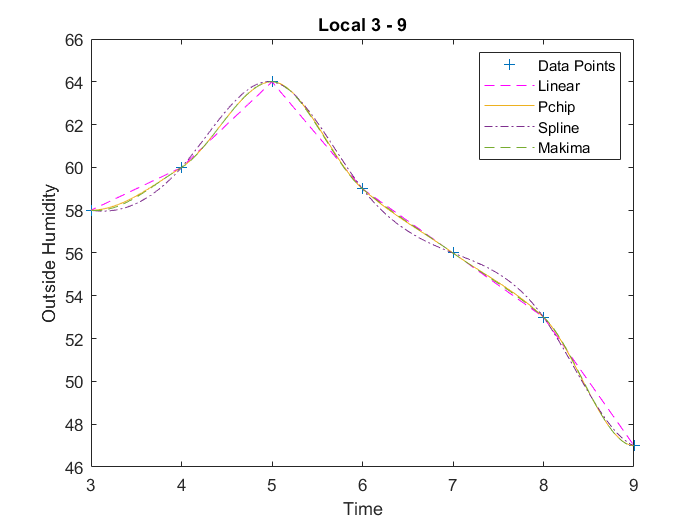


plot(Time,Sensor,'+')
f_combplot(xq,vq,x1,y1,Time,Sensor,Interval,Degree, xq3,vqq,p,s,m,Method1,Method2,Method3,Method4,Method5,Method6,Method7,text)
hold on
title('Local 3 - 9')
legend('Data Points','Linear','Pchip' , 'Spline', 'Makima')
xlim([3 9])
hold off
saveas(gcf,'pic_Interp_Local2.png');

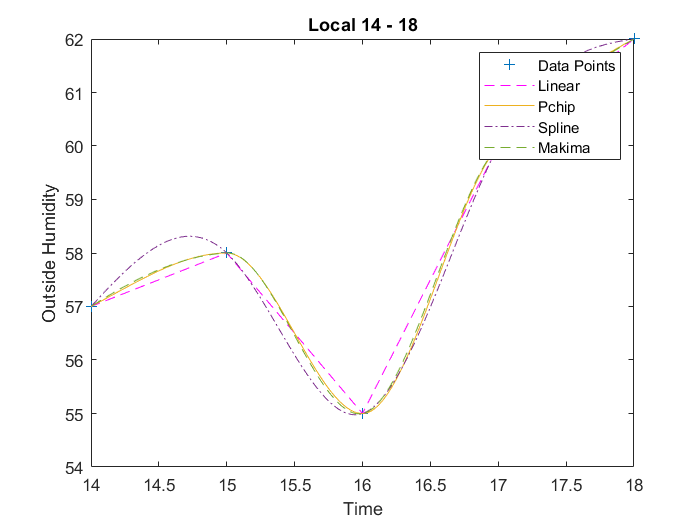




plot(Time,Sensor,'+')
f_combplot(xq,vq,x1,y1,Time,Sensor,Interval,Degree, xq3,vqq,p,s,m,Method1,Method2,Method3,Method4,Method5,Method6,Method7,text)
hold on
title('Local 14 - 18')
legend('Data Points','Linear','Pchip' , 'Spline', 'Makima')
xlim([14 18])
hold off
saveas(gcf,'pic_Interp_Local3.png');

## *=======  IT IS OVER THE PLOT ANALYSIS ======*